% Polynomial fitting
% x_data - dosage, mg/kg
% y_data – blood pressure, mmHg
x_data=[75, 62 54 43 37]; % vector with dose data
y_data=[3,13,17,25,28]; % vector with blood pressure data

a=polyfit(x_data, y_data,1) % defines fitting coefficients

a =    -0.6572   52.8199


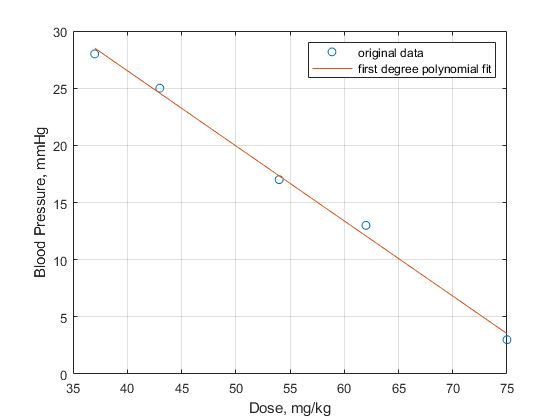

x_pol=linspace(min(x_data),max(x_data)); % vector with 100 (default) X-AXIS

% x values for plotting
y_fit =polyval(a,x_pol); % vector of y values calculated at x_pol Y DATAFIT
plot(x_data, y_data,'o', x_pol, y_fit) % plots polynomial and data points
xlabel('Dose, mg/kg'), ylabel('Blood Pressure, mmHg'),grid
legend(' original data',' first degree polynomial fit')